# Lab 2 State Feedback and Observer

A system (input $u\left(t\right)$ and output $y\left(t\right)$)is given by a simple transfer function:


$$G\left(s\right)=\frac{0\ldotp 1}{\;\left(1+s\right)\left(0\ldotp 1+s\right)}$$


## Question 1: model

Give a state space model **sysol** of this system with states:


$${\left\lbrack x_{1\;} \;\;x_{2\;} \right\rbrack }^T ={\left\lbrack y\left(t\right)\;\;\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}\right\rbrack }^T$$


and ouput ${\left\lbrack y\left(t\right)\;\;\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}\right\rbrack }^T$ (assuming both states can be measured)

From the transfer function it is easy to obtain the differential equation:


$$\overset{\ldotp \ldotp }{y} \left(t\right)+1\ldotp 1\;\overset{\ldotp }{y} \left(t\right)+0\ldotp 1\;y\left(t\right)=0\ldotp 1\;u\left(t\right)$$


And the state space model:

A = [0 1
    -0.1 -1];
B = [0;0.1];
C = [1 0
    0 1];
D = 0;
sysol = ss(A,B,C,D);

## Question 2: state feedback

We first compute a state feedback assuming the two states are measurable

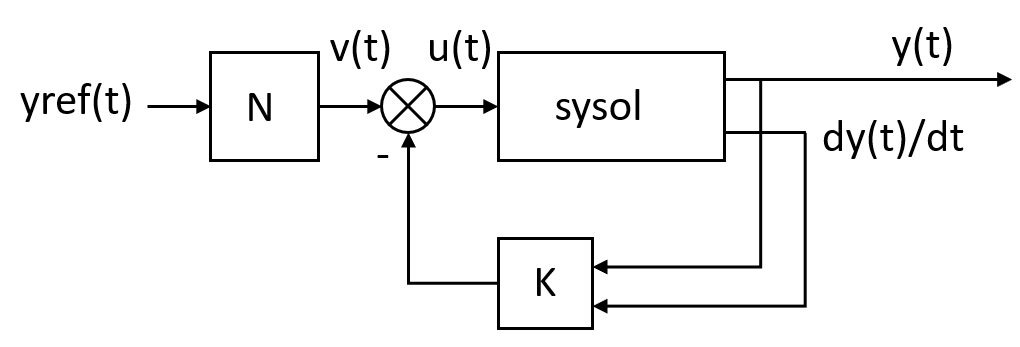

Using the matlab function **place**, compute the gain K of a state space feedback that guarantees a closed loop with damping $\sigma =0\ldotp 7$ and natural frequency $\omega {\;}_0 =1\;\textrm{rad}/s$

First compute the poles of the closed loop transfer function:

sigma = 0.7;
omega = 1;
P = roots([1 2*sigma*omega omega^2])

P =   -0.7000 + 0.7141i
  -0.7000 - 0.7141i


Then compute the state feedback

K = place(A,B,P)

K =     9.0000    4.0000


Give **syscl** the closed loop function between $v\left(t\right)$ and $y\left(t\right)$ 

syscl = feedback(sysol,K);
syscl = syscl(1,1)

syscl =
 
  A = 
         x1    x2
   x1     0     1
   x2    -1  -1.4
 
  B = 
        u1
   x1    0
   x2  0.1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Compute the value of the prefilter N for null steady state error with constant input. Method 1: compute the dcgain without prefilter N (matlab function dcgain) and compensate according to this result. Method 2: code the algorithm given page 71 of the slides;

N = 1/(dcgain(syscl))

N = 10

## Question 3: observer

We now assume that only $y\left(t\right)$ can be mesured. 

The dynamics of the observer is given by two poles: $\left\lbrack \begin{array}{cc}
-\textrm{po}-i\times \textrm{po} & -\textrm{po}+i\times \textrm{po}
\end{array}\right\rbrack$ with $\textrm{po}=10$

Compute the gain $L$ of the observer. 

po = 1;
L = place(A',[1 0]',[-po-1i*po -po+1i*po])'

L =     1.0000
    0.9000


Compute **sysobs** the state space model of the observer. The observer has input $\left\lbrack \begin{array}{c}
u\left(t\right)\\
y\left(t\right)
\end{array}\right\rbrack$and output $\left\lbrack \begin{array}{c}
\textrm{xest1}\left(t\right)\\
\textrm{xest2}\left(t\right)
\end{array}\right\rbrack$

sysobs = ss(A-L*[1 0],[L B],eye(2,2),zeros(1,1))

sysobs =
 
  A = 
       x1  x2
   x1  -1   1
   x2  -1  -1
 
  B = 
        u1   u2
   x1    1    0
   x2  0.9  0.1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



## Question 4: simulation, combination of observer and state feedback

The Simulink file lab2.slx is provided for the simulation.

If you did well you should verify that the simulated stp response is ok.

The following code allows to run the simulation from the command line, load and plot the interesting results.

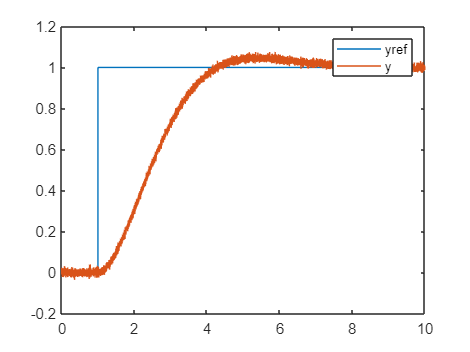

simout=sim('lab2');
t = simout.logsout{1}.Values.Time;
yref = simout.logsout{1}.Values.Data;
u = simout.logsout{2}.Values.Data;
y = simout.logsout{3}.Values.Data;
plot(t,yref,t,y);legend('yref','y');

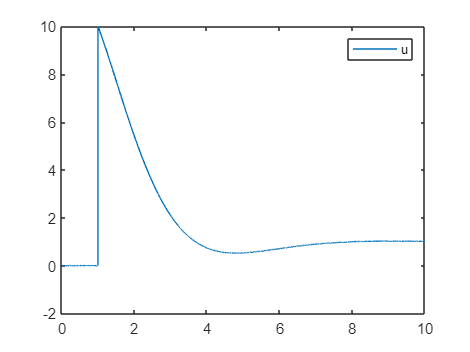

plot(t,u);legend('u');

Discuss the choice of:

- the closed loop natural frequency omega (try 10-100 times faster)

- the poles of the observer (try 10-100 times faster)

If I increase the closed loop natural frequency I increase the transient peak of the control u(t)

If I increase the magnitude of the poles of the observer I amplify the noise in my estimator, this noise comes back into u(t)